clear
clc
disp('===========REAKSİYON KİNETİĞİ HESAPLAMA===========')

===========REAKSİYON KİNETİĞİ HESAPLAMA===========


t =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


CA =     0.2000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ra =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


ra =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


==============Reaksiyon Grafikleri==============


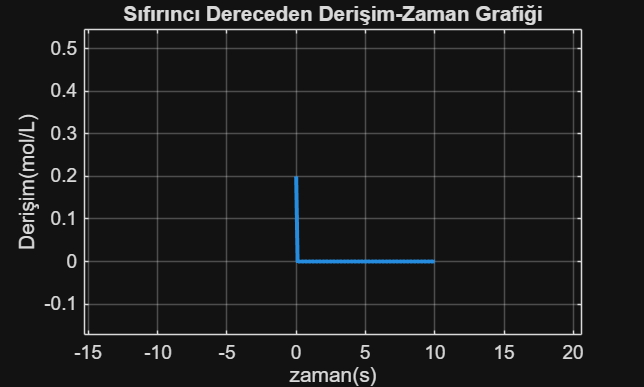

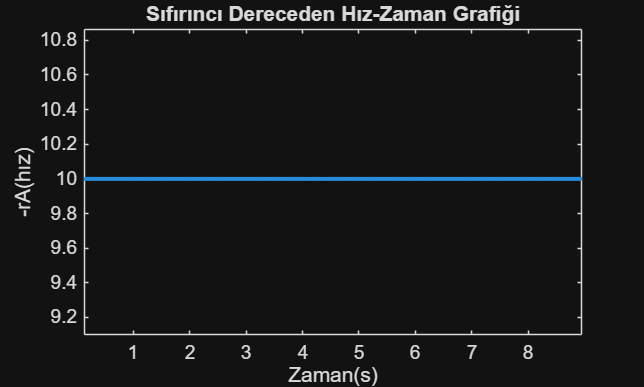

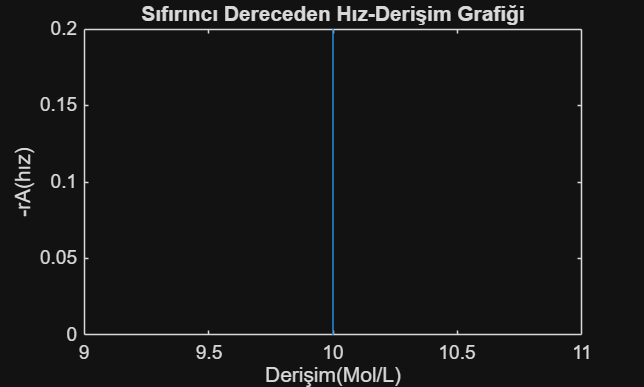

Hesaplanan derişim: 0.2000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan derişim: 0.0000 mol/L
Hesaplanan

Reaksiyon_Derecesi = input('reaksiyon derecesini giriniz(0,1,2): ');

if Reaksiyon_Derecesi == 0
    % Sıfırıncı dereceden reaksiyon

    CA0 = input('Başlangıç derişimini giriniz(mol/L): ');
    k = input('Reaksiyon hız sabitini giriniz(mol/(L*s)): ');
    tmax = input(' Maksimum Reaksiyon süresini giriniz(saniye): ');
    t = linspace(0 , tmax , 100)
    CA = CA0 - k*t;
    CA(CA < 0) = 0 %Programın negatif derişim hesaplamaması için sıfıra sabitle
    ra = k * ones(size(t)) % ra = -k tek elemanlı olduğu için boyut uyumsuzluğu oluşur size(t) t vektörünün bıyutunu verir ones ise tüm elemanları 1 olan vektör oluşturur.
    ra(ra < 0) = 0
    %Grafik çizimi
    disp('==============Reaksiyon Grafikleri==============')
 
    figure
    plot(t,CA,'LineWidth', 2)
    grid on
    xlabel('zaman(s)')
    ylabel('Derişim(mol/L)')
    title('Sıfırıncı Dereceden Derişim-Zaman Grafiği')
  

    figure
    grid on
    plot(t,ra,'LineWidth',2)
    xlabel('Zaman(s)')
    ylabel('-rA(hız)')
    title('Sıfırıncı Dereceden Hız-Zaman Grafiği')

    figure
    grid on
    plot(ra,CA)
    xlabel('Derişim(Mol/L)')
    ylabel('-rA(hız)')
    title('Sıfırıncı Dereceden Hız-Derişim Grafiği')

         

    if CA < 0
        disp('Derişim negatif olamaz, girdiğiniz değerleri kontrol ediniz.')
    else
        fprintf('Hesaplanan derişim: %.4f mol/L\n', CA)
  
    end

     elseif  Reaksiyon_Derecesi == 1
    % Birinci dereceden reaksiyon
    CA0 = input('Başlangıç derişimini giriniz(mol/L): ');
    k = input('Reaksiyon hız sabitini giriniz(1/s): ');
    tmax = input('Maksimum Reaksiyon süresini giriniz(saniye): ');
    t = linspace(0, tmax , 100)
    CA = CA0 * exp(-k*t);
    ra = k * CA

    figure
    grid on
    plot(t,CA)
    xlabel('Zaman(s)')
    ylabel('Derişim(Mol/L)')
    title('Birinci Dereceden Derişim-Zaman Grafiği')
  
    figure
    grid on
     plot(t,ra)
     xlabel('Zaman(s)')
     ylabel('Reaksiyon Hızı(-ra)')
     title('Birinci Dereceden Hız-Zaman Grafiği')

     figure
     grid on
     plot(CA,ra)
     xlabel('Derişim(Mol/Litre)')
     ylabel('Hız(rA)')
     title('Birinci Dereceden Hız-Derişim Grafiği')


    
    if CA < 0
        disp('Derişim negatif olamaz, girdiğiniz değerleri kontrol ediniz.')
    else
        fprintf('Hesaplanan derişim: %.4f mol/L\n', CA)
    end

elseif Reaksiyon_Derecesi == 2
    % İkinci dereceden reaksiyon
    CA0 = input('Başlangıç derişimini giriniz(mol/L): ');
    k = input('Reaksiyon hız sabitini giriniz(L/mol*s): ');
    tmax = input('Maksimum Reaksiyon süresini giriniz(saniye): ');
    t = linspace(0, tmax, 100)
    CA = 1 ./ (1/CA0 + k*t) % bu işlemi her bir sayı için ayrı ayrı yapmak istiyorsan "./" kullanmalısın!!!)
    ra = k * (CA .^ 2) % .^2 olmalı!!!

    figure
    grid on
    plot(t,CA)
    xlabel('Zaman(s)')
    ylabel('Derişim(Mol/L)')
    title('İkinci Dereceden Derişim-Zaman Grafiği')

    figure
    grid on
    plot(t,ra)
    xlabel('Zaman(s)')
    ylabel('Hız(-rA)')
    title('İkinci Dereceden Hız-Zaman Grafiği')
    figure
    grid on
    plot(CA,ra)
    xlabel('Derişim')
    ylabel('Reaksiyon hızı(-rA)')
    title('İkinci Dereceden Hız-Derişim Grafiği')

   

   
   
    if CA < 0
        disp('Derişim negatif olamaz, girdiğiniz değerleri kontrol ediniz.')
    else
        fprintf('Hesaplanan derişim: %.4f mol/L\n', CA)
    end

else
    disp('HATA: Geçersiz seçim! Lütfen 0, 1 veya 2 giriniz.')
end 





disp('===========HESAPLAMA TAMAMLANDI===========')

===========HESAPLAMA TAMAMLANDI===========
